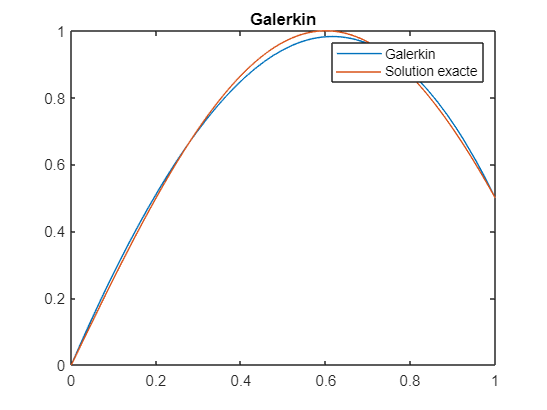

clear all
close all
syms a1 a2 x;
f=a1*(x-x^3)+a2*(x^2-x^3)+0.5*x^3;

residual=diff(diff(f,x,1),x,1) + f - (1- (5*pi/6)^2)*(sin(5*pi*x/6));

w1=diff(f,a1);
w2=diff(f,a2);

eq1=int(residual*w1,x,0,1);
eq2=int(residual*w2,x,0,1);

S=solve(eq1,eq2,a1,a2);
S1=S.a1;
S2=S.a2;

digits(6);
a1=vpa(S1);
a2=vpa(S2);

fgalerk=subs(f);
f_exacte=sin(5*pi*x/6);

fplot(fgalerk, [0,1])
hold on
X=0:0.01:1;
Y=sin(5*pi*X/6);
plot(X,Y)
legend("Galerkin","Solution exacte")
title("Galerkin")
hold off

## Sub-domains

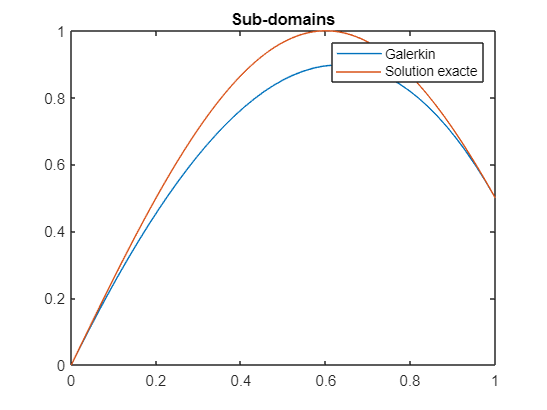

syms c1 c2 x;
fsd=c1*(x-x^3)+c2*(x^2-x^3)+0.5*x^3;
sdresidual=diff(diff(fsd,x,1),x,1) +fsd - (1- (5*pi/6)^2)*(sin(5*pi*x/6));
sdeq1=int(sdresidual,x,0,0.5);
sdeq2=int(sdresidual,x,0.5,1);
sdS=solve(sdeq1,sdeq2,c1,c2);
sdS1=sdS.c1;
sdS2=sdS.c2;
c1=vpa(sdS1);
c2=vpa(sdS2);
gsd=subs(fsd);

fplot(gsd,[0,1])
hold on
X=0:0.01:1;
Y=sin(5*pi*X/6);
plot(X,Y)
legend("Galerkin","Solution exacte")
title("Sub-domains")
hold off

## least square

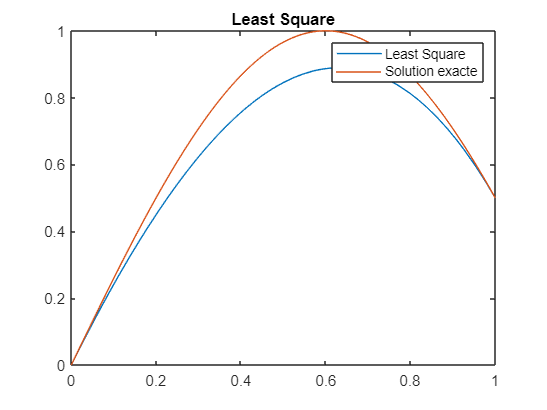

syms b1 b2 x;
fls=b1*(x-x^3)+b2*(x^2-x^3)+0.5*x^3;
lsresidual=diff(diff(fls,x,1),x,1) +fls - (1- (5*pi/6)^2)*(sin(5*pi*x/6));
FF=int(lsresidual*lsresidual,x,0,1);

lseq1=diff(FF,b1);
lseq2=diff(FF,b2);
lsS=solve(lseq1,lseq2,b1,b2);
lsS1=lsS.b1;
lsS2=lsS.b2;
b1=vpa(lsS1);
b2=vpa(lsS2);
gls=subs(fls);

fplot(gls,[0,1])
hold on
X=0:0.01:1;
Y=sin(5*pi*X/6);
plot(X,Y)
legend("Least Square","Solution exacte")
title("Least Square")
hold off

a1,a2

$$a1 = 2.93212$$

$$a2 = -1.74858$$

b1,b2

$$b1 = 2.55599$$

$$b2 = -1.40791$$

c1,c2

$$c1 = 2.57766$$

$$c2 = -1.40847$$

X_evaluate=0:0.01:1;
Fgalerk=matlabFunction(f);
Fls=matlabFunction(fls);
Fsd=matlabFunction(fsd);
F_exacte=matlabFunction(f_exacte);

E1=mean(abs(F_exacte(X)-Fgalerk(a1,a2,X)))

Error using float
Expected TOTALBITS to be one of these types:

char, string

Instead its type was sym.

Error in float (line 52)
        validateattributes(TotalBits, {'char', 'string'}, {'scalartext'}, fcn_name, 'TOTALBITS');       

E2=mean(abs(F_exacte(X)-Fsd(c1,c2,X)))
E2=mean(abs(F_exacte(X)-Fls(b1,b2,X)))


clear all
close all
a=sym('a',[100 1]);
syms x;
f(1)=(x-1);
f(2)=(x-x^2);
N=5;

for i=3:N
    f(i)=f(i-1)*x;
end
fg=x/2;
for i=1:N
    fg= a(i)*f(i)
end
residual=diff(diff(f,x,1),x,1) + f - (1- (5*pi/6)^2)*(sin(5*pi*x/6));

w1=diff(f,a1);
w2=diff(f,a2);

eq1=int(residual*w1,x,0,1);
eq2=int(residual*w2,x,0,1);

S=solve(eq1,eq2,a1,a2);
S1=S.a1;
S2=S.a2;

digits(6);
a1=vpa(S1);
a2=vpa(S2);

fgalerk=subs(f);
f_exacte=sin(5*pi*x/6);

fplot(fgalerk, [0,1])
hold on
X=0:0.01:1;
Y=sin(5*pi*X/6);
plot(X,Y)
legend("Galerkin","Solution exacte")
title("Galerkin")
hold off